# Evaluate Actuator Rating for Torque and Power of Robot Arm

This example shows how to evaluate the actuator rating of a 6-axis articulated robot.

Copyright 2023 - 2024 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('RobotDesignOverview.html')).

## Understand Actuator Rating

A robot arm actuator is a component or mechanism responsible for generating the physical motion of the robotic arm. For an articulated robot, all the joints are revolute, and a rotary actuator moves a joint. The motor must support the weight of the robot itself and move the payload as required. Different joints require different motor capacity, as the force acting on each joint is different. For example, the motor at the shoulder would have to support higher weight and would be of larger power rating than the motor at the wrist joint.

This example shows how to evaluate the joint actuator ratings for a motion that requires maximum power from the actuator, such as a motion where robot arm is extended to its maximum. To do this, first find the workspace envelope of the robot. The two motions considered are the motion along the front envelope and the motion along the top envelope. To determine the work envelope of the robot, see [Determine Work Envelope for an Articulated Robot](matlab:open('DetermineEnvelopeWorkflow.mlx')).

## Evaluate Actuator Rating for Parametric Robot

Setup the parameters and run the script for the parametric robot model actuator rating. Compute the maximum torque and maximum power required by the robot actuator at the base, shoulder and elbow joint of the articulated robot. The path followed for the rating computation is the outer workspace envelope which has the robot arm fully extended and exerts maximum load for the actuator joints. 

- Get the front and the top point cloud of the workspace area.

- Generate envelope from the point cloud to get the maximum reach.

- Create a trajectory along the envelope in front and top workspace.

- Run the simulation and record torque and speed to compute power.

For rating with payload, attach a dummy payload rigidly to the end tool of the arm.

modelRobot = 'ParametricRobotModel'; % robot arm subsystem name
modelName="ActuatorRatingModel"; % Model with angle actuation at joints
endEffectorName = "Body5"; % end effector for workspace computation
simTime = 3; % [s] simulation time for the robot to perform one rotation

load_system(modelName)
LoadParametricRating; % Set the config model for Parametric robot

Configuring the actuator rating model with Parametric robot...


Generate the volume sphere of the robot
Generate the envelope of front-view
Generate the boundary of front-view


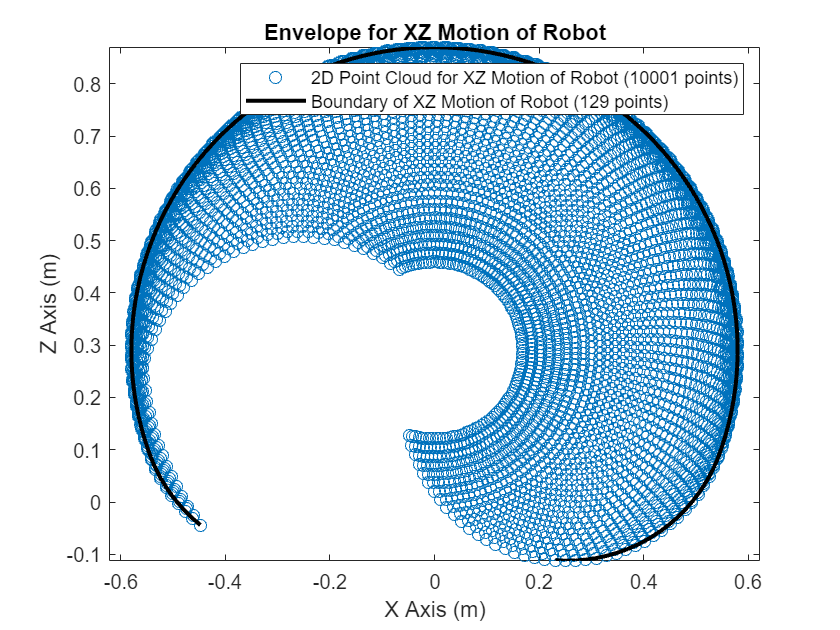

Generate the waypoints for front-view motion
Calculate the power consumed by each joint from the simulation of
Plot the measurements of the simulation of the front-view motion


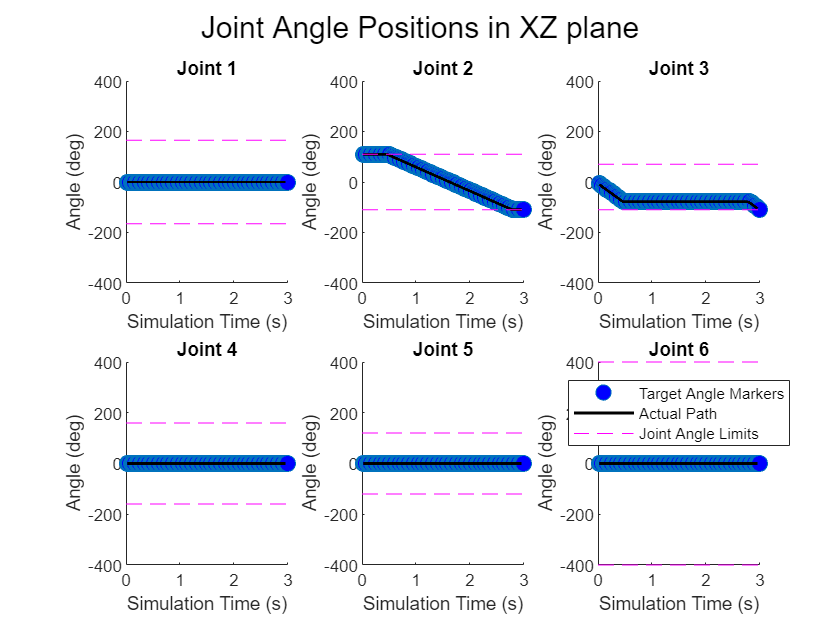

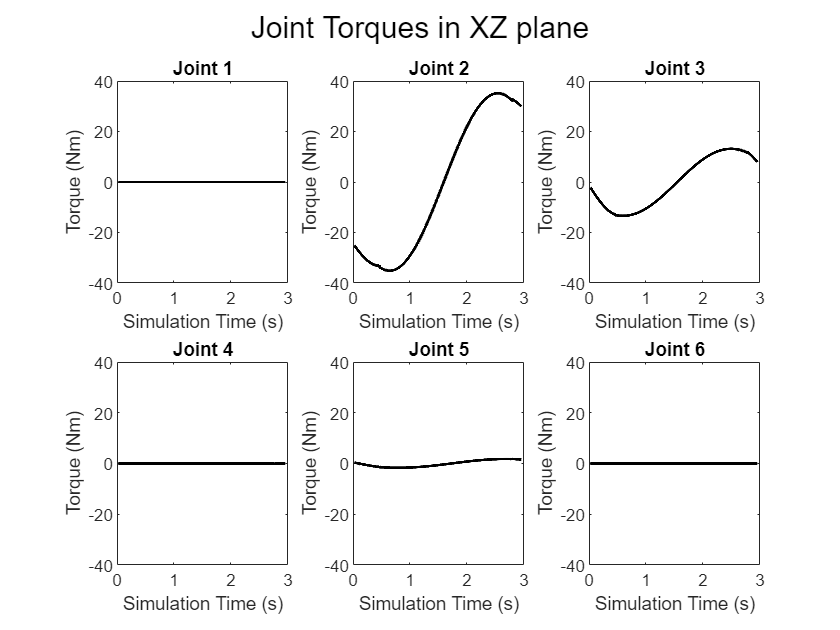

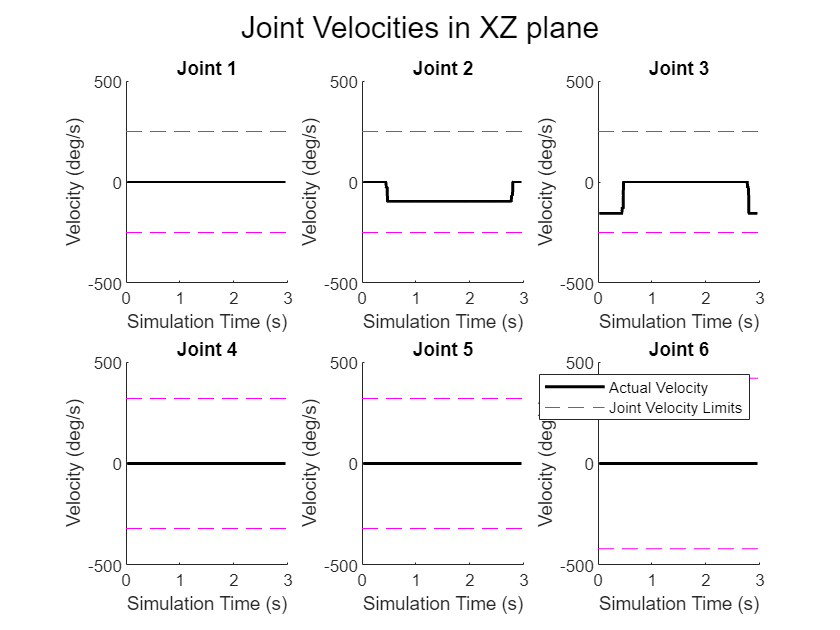

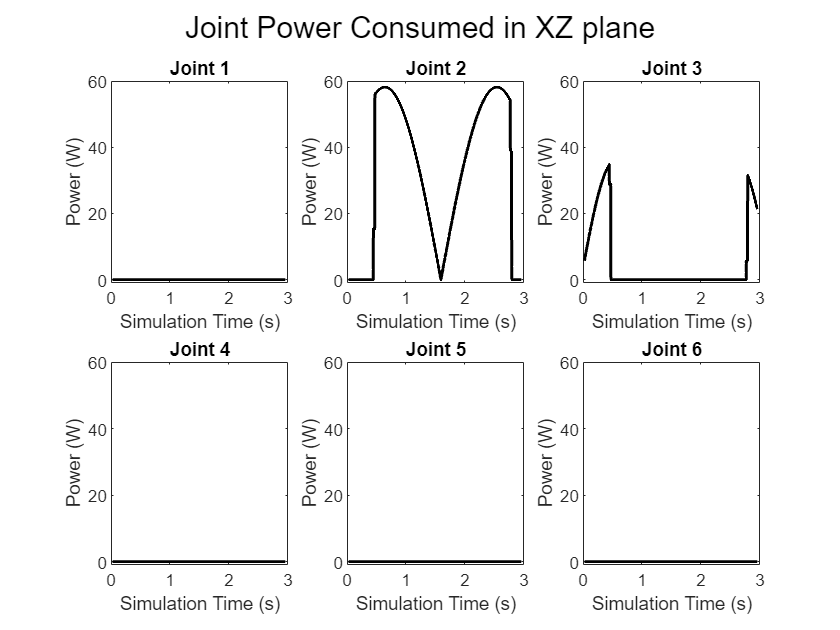

Generate the envelope of top-view
Generate the boundary of the top-view


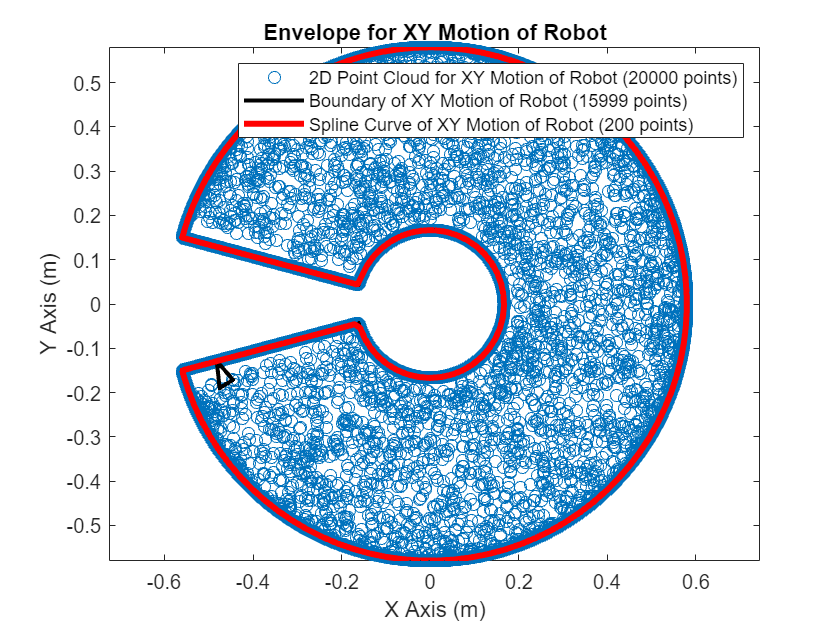

Generate the waypoints for top-view motion
Simulate the top-view motion


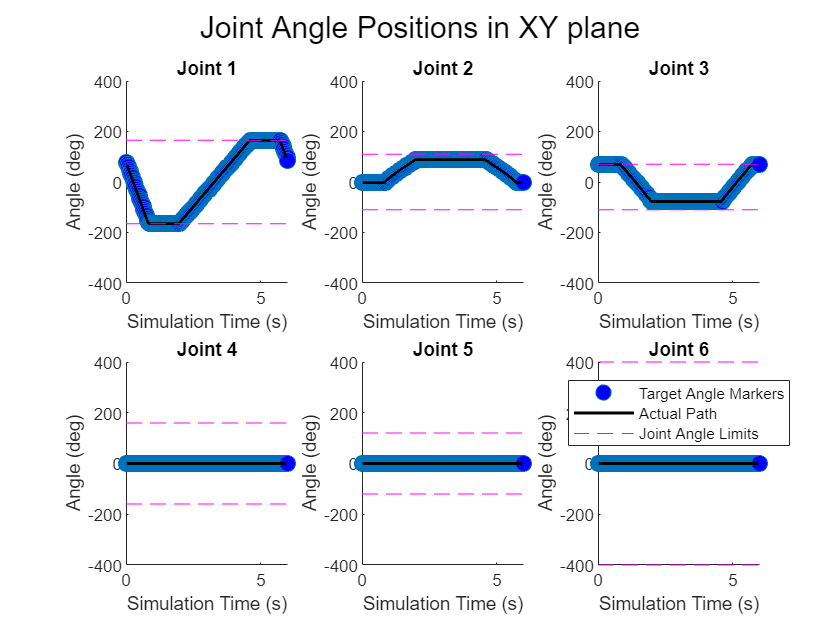

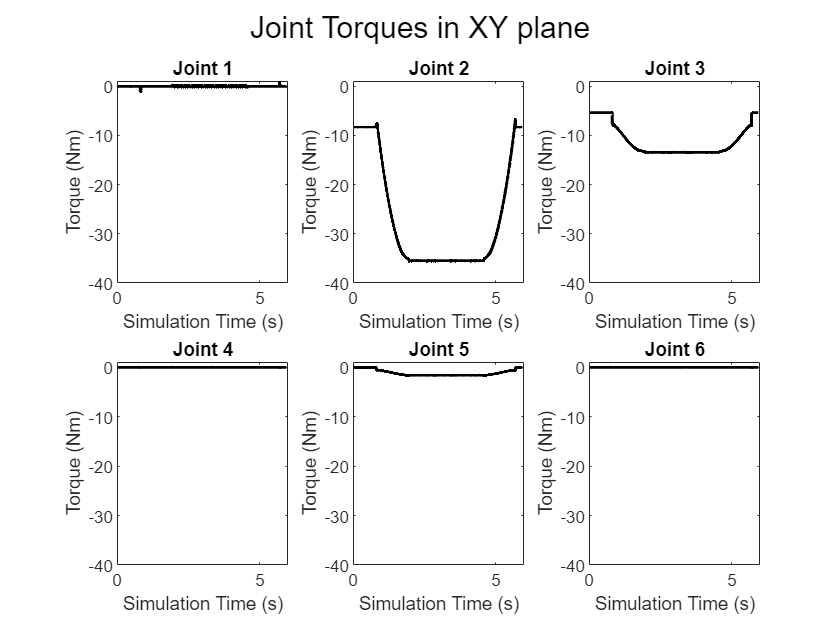

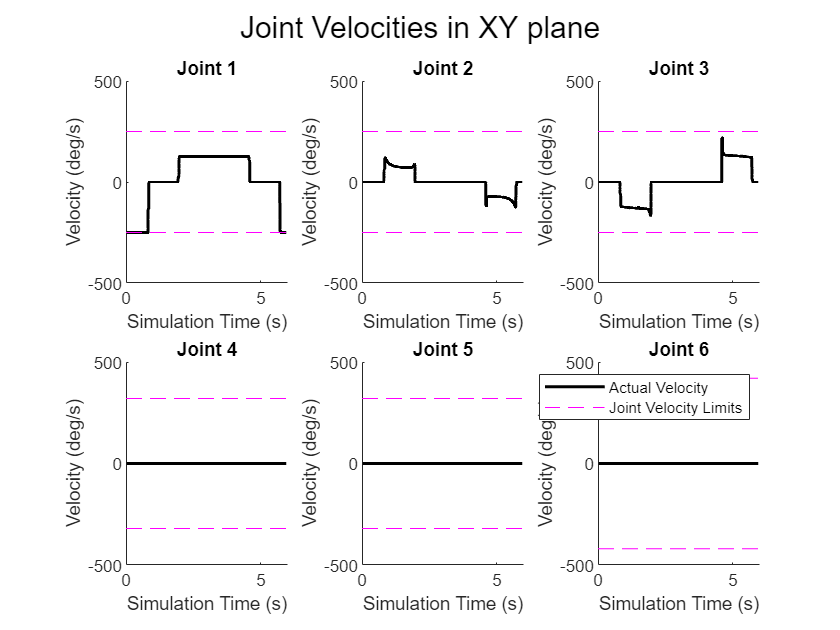

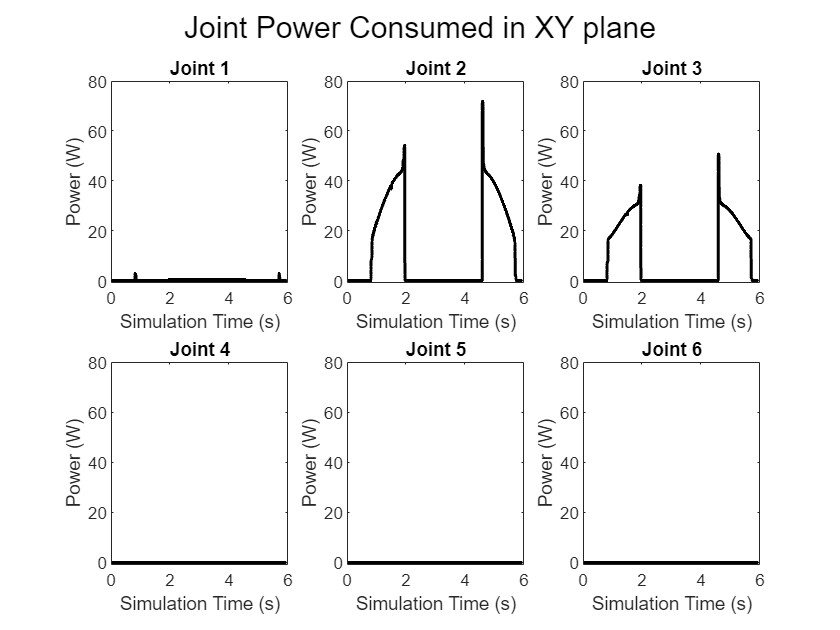

roboticArmEnvelopeAndRating(modelRobot,modelName,endEffectorName,simTime)

close_system(modelName,0)

## Actuator Ratings of Parametric Robot

Actuator maximum power and maximum torque rating  of parametric robot for the motion discussed in previous sections.

table = tableActuatorRating('ratingsFrontParametricRobotModel.mat','ratingsTopParametricRobotModel.mat');

actuatorDataTable = array2table([table.joint ,table.torque, table.vel, table.power],...
           'VariableNames',table.Case )

actuatorDataTable = 3×4 table
      Joint      Max Torque (Nm)    Max Velocity (deg/s)    Max Power (W)
    _________    _______________    ____________________    _____________

    "Joint 1"      "0.916079"            "187.2917"           "2.99453"  
    "Joint 2"      "35.2021"             "116.8923"           "71.8177"  
    "Joint 3"      "13.3157"             "218.4763"           "50.7746"  


## Useful Links

For comparison between CAD geometry robot and its equivalent parametric robot [click here](matlab:open('CompareRatingCADandParametric.mlx')).

For workspace identification of robot arm see [EnvelopeWorkflow](matlab:open('DetermineEnvelopeWorkflow.mlx')).